## Thumb inverse analysis from stored dataset

### Reading dataset

clear
clc

s = settings;
s.matlab.editor.AllowFigureAnimation.PersonalValue = true;

ans_theta1 = readmatrix('theta1-inverse-mapping-500x500.xlsx');
ans_theta1_ = readmatrix('theta1_-inverse-mapping-500x500.xlsx');

steps = 500;
steps2 = 500;

shift1 = 2;
shift2 = 5;
shift3 = 2;

query_theta0_min = -56.5331 + shift1;
query_theta0_max = 42.0468 - shift2;

query_theta0__min = -71.1308 + shift3;
query_theta0__max = 31.7320 - shift3;

val_theta0 = linspace(query_theta0_min,query_theta0_max,steps);
val_theta0_ = linspace(query_theta0__min,query_theta0__max,steps2);

extraInputs = {'interpreter','latex','fontsize',14}; % name, value pairs
legendInputs = {'location', 'southoutside', 'orientation', 'horizontal','interpreter','latex','fontsize',12}; % name, value pairs

### Domain plot

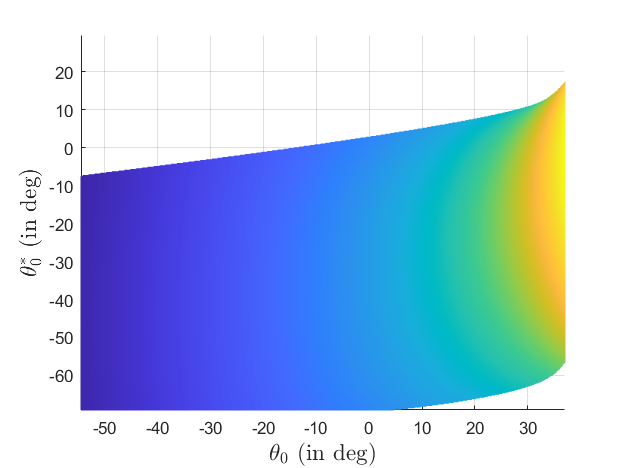

q_theta0 = -20;
q_theta0_ = -30;
xPlane = [q_theta0, q_theta0, q_theta0, q_theta0];
yPlane = [-70, -70, 30, 30];
zPlane = [0, 50, 50, 0];

xPlane2 = [-60, -60, 40, 40];
yPlane2 = [q_theta0_, q_theta0_, q_theta0_, q_theta0_];
zPlane2 = [0, 50, 50, 0];

f = figure();
set(f,'Units',"centimeters","OuterPosition",[0, 0, 13.2, 9.9]);
p = mesh(val_theta0, val_theta0_, ans_theta1.');
hold on
% patch(xPlane, yPlane, zPlane, 'r', 'facealpha', 0.5);
% patch(xPlane2, yPlane2, zPlane2, 'r', 'facealpha', 0.5);
xlim([query_theta0_min, query_theta0_max]);
ylim([query_theta0__min, query_theta0__max]);
xlabel('$\theta_0$ (in deg)', extraInputs{:});
ylabel('$\theta_0^*$ (in deg)',extraInputs{:});

view([-0 90.0])
exportgraphics(f, 'figures/theta1-inverse-mapping-top.png', 'Resolution', 600);

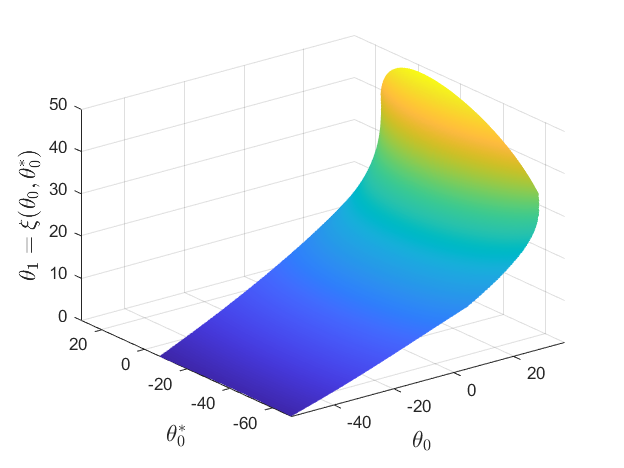


f = figure();
set(f,'Units',"centimeters","OuterPosition",[0, 0, 13.2, 9.9]);
p = mesh(val_theta0, val_theta0_, ans_theta1.');
hold on
% patch(xPlane, yPlane, zPlane, 'r', 'facealpha', 0.5);
% patch(xPlane2, yPlane2, zPlane2, 'r', 'facealpha', 0.5);
xlim([query_theta0_min, query_theta0_max]);
ylim([query_theta0__min, query_theta0__max]);
xlabel('$\theta_0$', extraInputs{:});
ylabel('$\theta_0^*$',extraInputs{:});
zlabel('$\theta_1 = \xi(\theta_0, \theta_0^*)$', extraInputs{:});
exportgraphics(f, 'figures/theta1-inverse-mapping-iso.png', 'Resolution', 600);

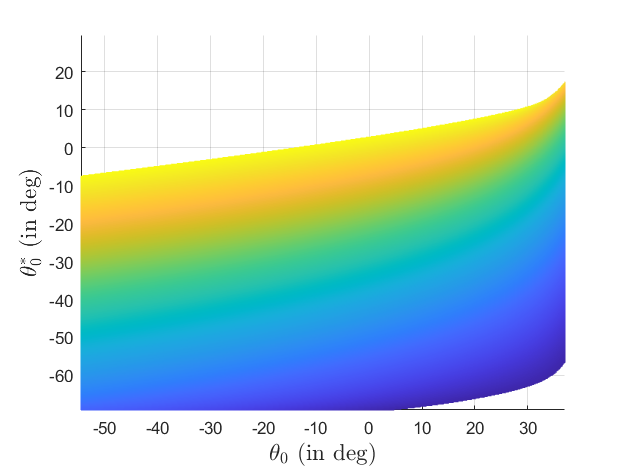


zPlane = [-30, 60, 60, -30];
zPlane2 = [-30, 60, 60, -30];

f = figure();
set(f,'Units',"centimeters","OuterPosition",[0, 0, 13.2, 9.9]);
p = mesh(val_theta0, val_theta0_, ans_theta1_.');
hold on
% patch(xPlane, yPlane, zPlane, 'r', 'facealpha', 0.5);
% patch(xPlane2, yPlane2, zPlane2, 'r', 'facealpha', 0.5);
xlim([query_theta0_min, query_theta0_max]);
ylim([query_theta0__min, query_theta0__max]);
xlabel('$\theta_0$ (in deg)', extraInputs{:});
ylabel('$\theta_0^*$ (in deg)',extraInputs{:});

view([0 90.0])
exportgraphics(f, 'figures/theta1_-inverse-mapping-top.png', 'Resolution', 600);

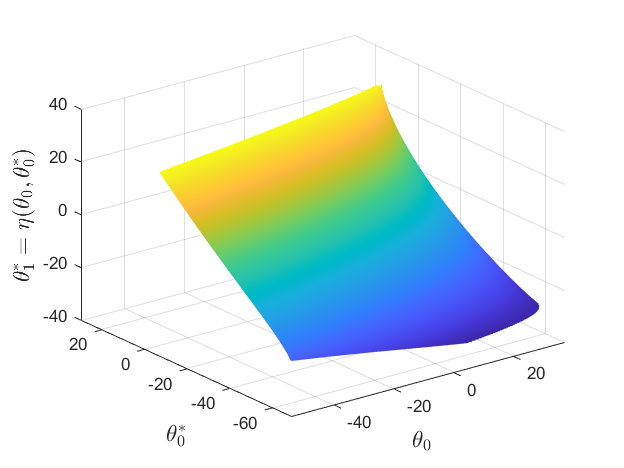


f = figure();
set(f,'Units',"centimeters","OuterPosition",[0, 0, 13.2, 9.9]);
p = mesh(val_theta0, val_theta0_, ans_theta1_.');
hold on
% patch(xPlane, yPlane, zPlane, 'r', 'facealpha', 0.5);
% patch(xPlane2, yPlane2, zPlane2, 'r', 'facealpha', 0.5);
xlim([query_theta0_min, query_theta0_max]);
ylim([query_theta0__min, query_theta0__max]);
xlabel('$\theta_0$', extraInputs{:});
ylabel('$\theta_0^*$',extraInputs{:});
zlabel('$\theta_1^* = \eta(\theta_0, \theta_0^*)$', extraInputs{:});
exportgraphics(f, 'figures/theta1_-inverse-mapping-iso.png', 'Resolution', 600);

### Inverse function domain plot

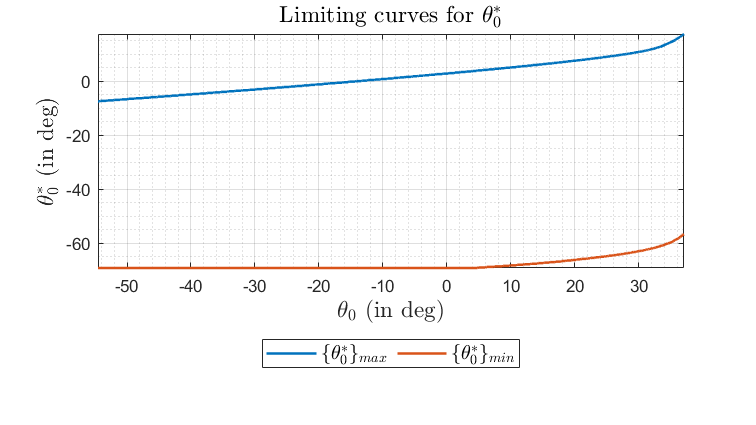

x = val_theta0;
y = [];
y1 = [];
for i = 1:steps
    j = steps2;
    while isnan(ans_theta1_(i,j))
        j = j - 1;
    end
    y(i) = val_theta0_(j);
    j = 1;
    while isnan(ans_theta1_(i,j))
        j = j + 1;
    end
    y1(i) = val_theta0_(j);
end

f = figure();
plot(x, y, x, y1, 'LineWidth', 1.5);
[title_inputs,axes_title_inputs,legend_inputs] = plot_defaults(f,16,9,14,14,12);
legend('$\{\theta_0^* \}_{max}$','$\{\theta_0^* \}_{min}$',legend_inputs{:});
xlabel('$\theta_0$ (in deg)', axes_title_inputs{:});
ylabel('$\theta_0^*$ (in deg)',axes_title_inputs{:});
title('Limiting curves for $\theta_0^*$', title_inputs{:});
exportgraphics(f, 'figures/theta0-domain-plot.png', 'Resolution', 600);

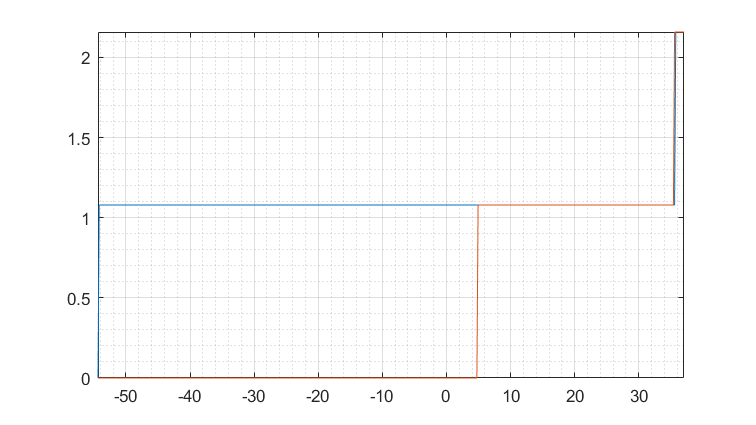

dy = y(2:end) - y(1:(end-1));
dy1 = y1(2:end) - y1(1:(end-1));
dx = x(2:end) - x(1:(end-1));

slope = dy./dx;
slope1 = dy1./dx;

len = size(slope);
max_slope = zeros(len);
max_slope1 = zeros(len);
for i = 1:len(2)
   max_slope(i) = max(slope(1:i));
   max_slope1(i) = max(slope1(1:i));
end

f = figure();
plot(x(2:end), max_slope, x(2:end), max_slope1);
[title_inputs,axes_title_inputs,legend_inputs] = plot_defaults(f,16,9,14,14,12);

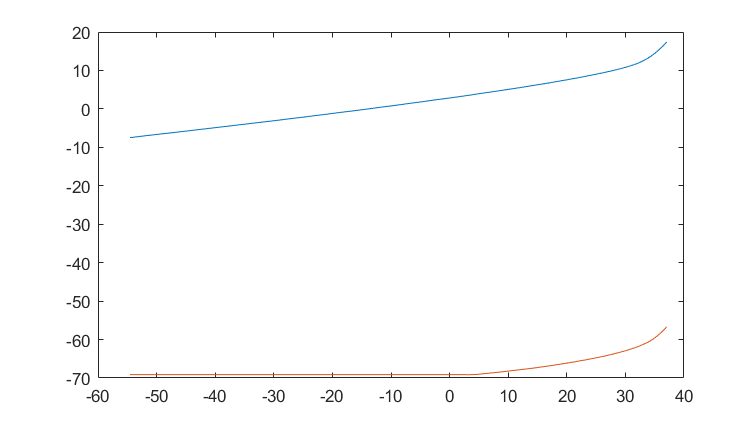

y_smooth = smoothdata(y,'loess',35);
y1_smooth = smoothdata(y1, 'loess',35);
plot(x, y_smooth, x, y1_smooth);

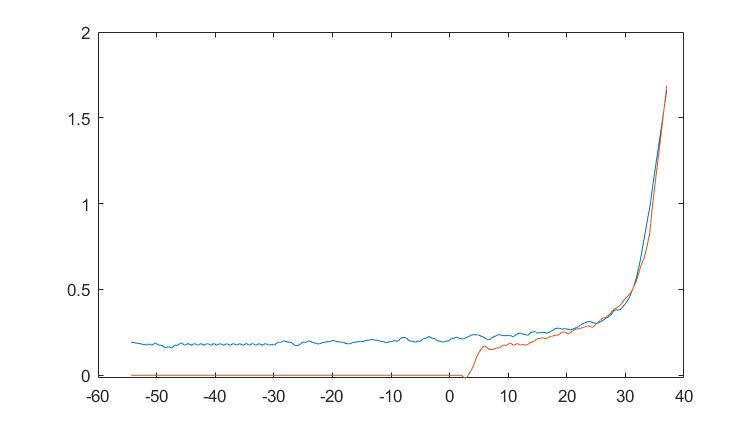

dy_smooth = y_smooth(2:end) - y_smooth(1:(end-1));
dy1_smooth = y1_smooth(2:end) - y1_smooth(1:(end-1));
plot(x(2:end), dy_smooth./dx, x(2:end), dy1_smooth./dx);

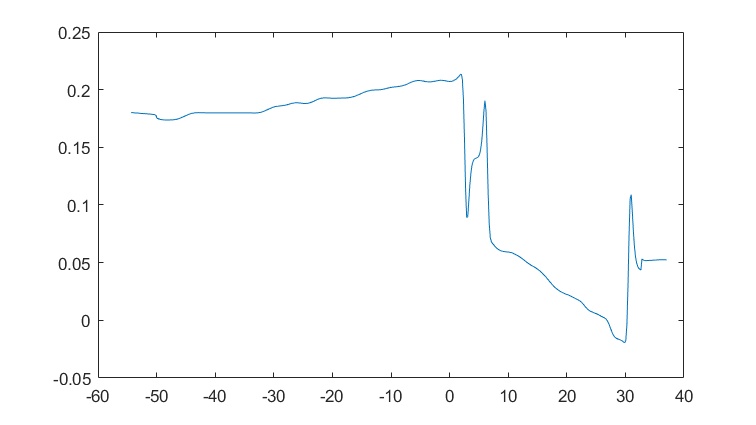

diffy = y_smooth - y1_smooth;
diffy_smooth = smoothdata(diffy,'rlowess',50);
d_diffy_smooth = diffy_smooth(2:end) - diffy_smooth(1:(end-1));
plot(x(2:end),d_diffy_smooth./dx);

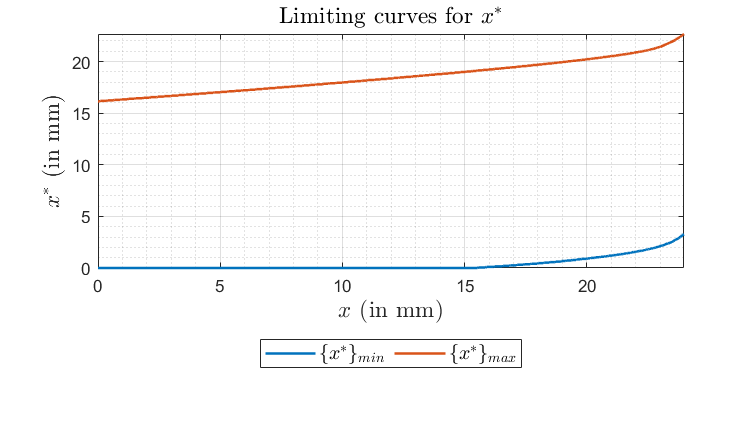

x_ = x * (pi/180) * 15;
x_ = x_ - x_(1);

y_max = (y - y1(1) * ones(size(y))) *(pi/180)*15;
y_min = (y1 - y1(1) * ones(size(y))) *(pi/180)*15;

f = figure();
plot(x_, y_min, x_, y_max, 'LineWidth', 1.5);
[title_inputs,axes_title_inputs,legend_inputs] = plot_defaults(f,16,9,14,14,12);
legend('$\{x^* \}_{min}$','$\{x^* \}_{max}$',legend_inputs{:});
xlabel('$x$ (in mm)',axes_title_inputs{:});
ylabel('$x^*$ (in mm)',axes_title_inputs{:});
title('Limiting curves for $x^*$',title_inputs{:});
exportgraphics(f, 'figures/x_-domain-plot.png', 'Resolution', 600);

x_max = x_(end);
x__max = y_max(end);
percent_x = 99;
percent_x_ = 15;

domain_x_ = linspace(0,y_max(end),steps);
domain_x = x_;
predict_theta1 = interp2(domain_x,domain_x_,ans_theta1.',(percent_x/100)*x_max,(percent_x_/100)*x__max)

predict_theta1 = 33.1368

predict_theta1_ = interp2(domain_x,domain_x_,ans_theta1_.',(percent_x/100)*x_max,(percent_x_/100)*x__max)

predict_theta1_ = -28.7164

### Verification of inversion

q_theta0 = -20;
q_theta0_ = -30;

lambda = 0;
lambda_ = 0;

previd = 0;
nextid = 0;
previd_ = 0;
nextid_ = 0;

for i = 2:steps
    if val_theta0(i) > q_theta0
        previd = i-1;
        nextid = i;
        lambda = (q_theta0 - val_theta0(i)) / (val_theta0(i-1) - val_theta0(i));
        break;
    end
end

for i = 2:steps2
    if val_theta0_(i) > q_theta0_
        previd_ = i-1;
        nextid_ = i;
        lambda_ = (q_theta0_ - val_theta0_(i)) / (val_theta0_(i-1) - val_theta0_(i));
        break;
    end
end

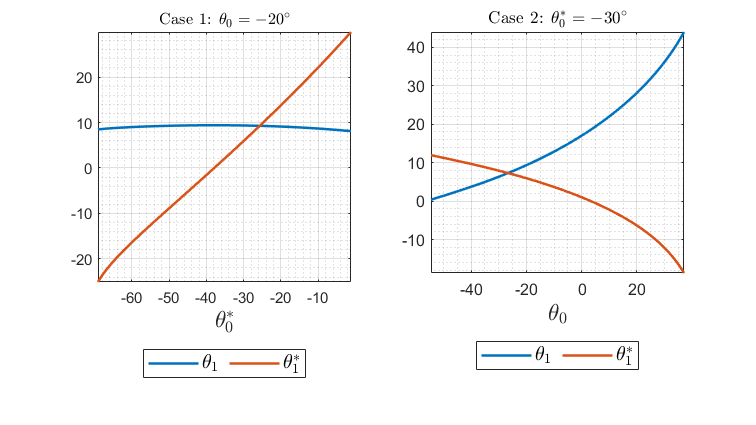

x1 = val_theta0_;
case1_sim_theta1 = (ans_theta1(previd,:) * lambda + ans_theta1(nextid,:) * (1-lambda));
case1_sim_theta1_ = (ans_theta1_(previd,:) * lambda + ans_theta1_(nextid,:) * (1-lambda));

f = figure();

ax = subplot(1,2,1);
plot(x1, case1_sim_theta1, x1, case1_sim_theta1_, 'LineWidth', 1.5);
[title_inputs,axes_title_inputs,legend_inputs] = plot_defaults(f,16,9,16,14,12);
xlabel('$\theta_0^*$',axes_title_inputs{:});
title('Case 1: $\theta_0 = -20^\circ$', title_inputs{:});
legend('$\theta_1$', '$\theta_1^*$',legend_inputs{:});

xlim1 = xlim;

x2 = val_theta0;
case2_sim_theta1 = (ans_theta1(:,previd_) * lambda_ + ans_theta1(:,nextid_) * (1-lambda_));
case2_sim_theta1_ = (ans_theta1_(:,previd_) * lambda_ + ans_theta1_(:,nextid_) * (1-lambda_));

ax2 = subplot(1,2,2);
plot(x2, case2_sim_theta1, x2, case2_sim_theta1_, 'LineWidth', 1.5);
[title_inputs,axes_title_inputs,legend_inputs] = plot_defaults(f,16,9,16,14,12);
xlabel('$\theta_0$',axes_title_inputs{:});
title('Case 2: $\theta_0^* = -30^\circ$', title_inputs{:});
legend('$\theta_1$', '$\theta_1^*$',legend_inputs{:});

xlim2 = xlim;

exportgraphics(f, 'figures/inverse-verification-plots.png', 'Resolution', 600);

xlim1

xlim1 =   -69.1308   -1.1750


case1_init_pose_theta1 = interp1(val_theta0_, case1_sim_theta1, xlim1(1), 'linear')

case1_init_pose_theta1 = 8.4742

case1_init_pose_theta1_ = interp1(val_theta0_, case1_sim_theta1_, xlim1(1), 'linear')

case1_init_pose_theta1_ = -25.0898

xlim2

xlim2 =   -54.5331   37.0468


case2_init_pose_theta1 = interp1(val_theta0, case2_sim_theta1, xlim2(1), 'linear')

case2_init_pose_theta1 = 0.3779

case2_init_pose_theta1_ = interp1(val_theta0, case2_sim_theta1_, xlim2(1), 'linear')

case2_init_pose_theta1_ = 11.9487

### Case 1: Initial Pose

#### Front View

% theta0* constant
f = figure();
set(f,'Units',"centimeters","OuterPosition",[0, 0, 9.9, 13.2]);
thumb_simulation(case1_init_pose_theta1 * ones(size(case1_sim_theta1)), case1_init_pose_theta1_ * ones(size(case1_sim_theta1_)), [0 -1 0]);

(-2.000001e+01, -6.913088e+01)


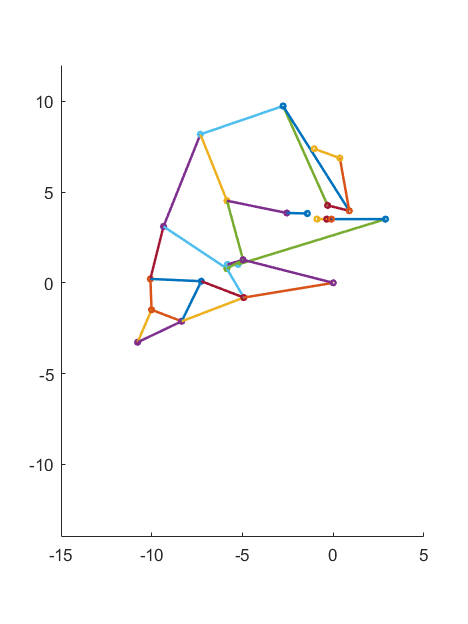

exportgraphics(f, 'figures/inverse-verification-case1-init-pose-front.png', 'Resolution', 600);

#### Top View

f = figure();
set(f,'Units',"centimeters","OuterPosition",[0, 0, 9.9, 13.2]);
thumb_simulation(case1_init_pose_theta1 * ones(size(case1_sim_theta1)), case1_init_pose_theta1_ * ones(size(case1_sim_theta1_)), [0 0 1]);

(-2.000001e+01, -6.913088e+01)


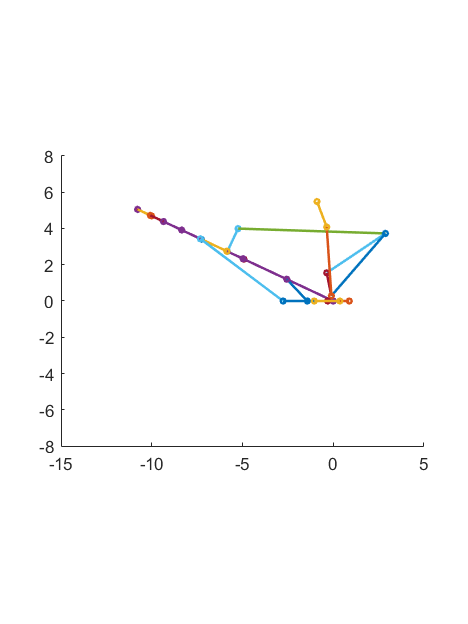

exportgraphics(f, 'figures/inverse-verification-case1-init-pose-top.png', 'Resolution', 600);

### Case 1: Final Pose

#### Front View

f = figure();
set(f,'Units',"centimeters","OuterPosition",[0, 0, 9.9, 13.2]);
thumb_simulation(case1_sim_theta1, case1_sim_theta1_, [0 -1 0]);

(-2.000001e+01, -6.913088e+01)


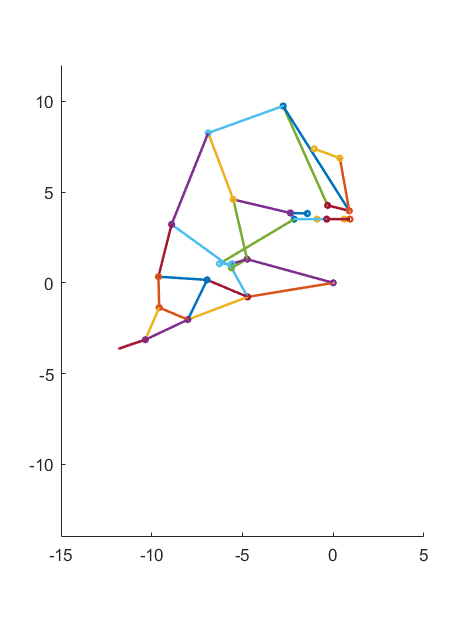

exportgraphics(f, 'figures/inverse-verification-case1-final-pose-front.png', 'Resolution', 600);

#### Top View

f = figure();
set(f,'Units',"centimeters","OuterPosition",[0, 0, 9.9, 13.2]);
thumb_simulation(case1_sim_theta1, case1_sim_theta1_, [0 0 1]);

(-2.000001e+01, -6.913088e+01)


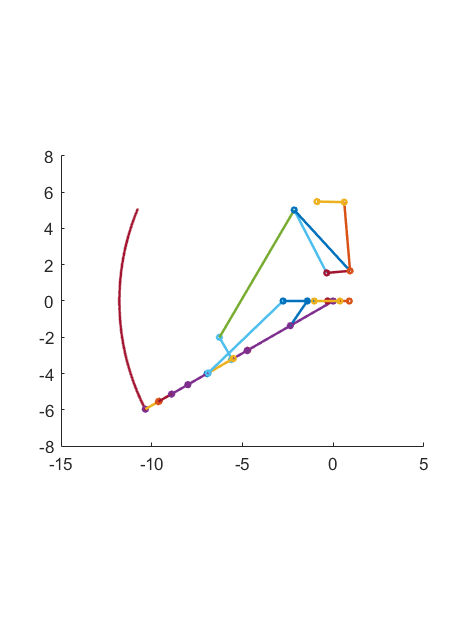

exportgraphics(f, 'figures/inverse-verification-case1-final-pose-top.png', 'Resolution', 600);

### Case 2: Initial Pose

#### Front View

% theta0 constant
f = figure();
set(f,'Units',"centimeters","OuterPosition",[0, 0, 9.9, 13.2]);
thumb_simulation(case2_init_pose_theta1 * ones(size(case2_sim_theta1.')), case2_init_pose_theta1_ * ones(size(case2_sim_theta1_.')), [0 -1 0]);

(-5.453337e+01, -2.999997e+01)


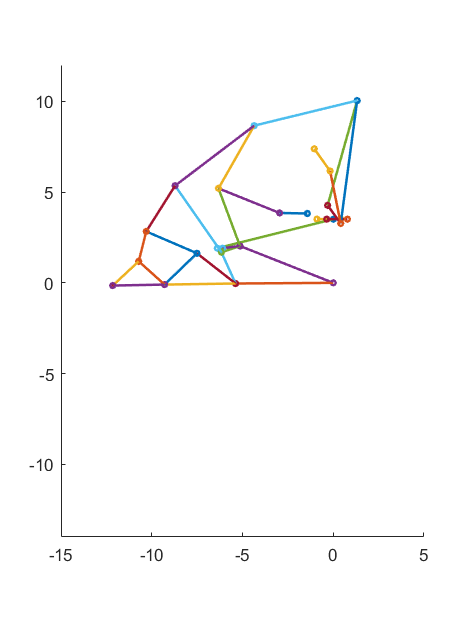

exportgraphics(f, 'figures/inverse-verification-case2-init-pose-front.png', 'Resolution', 600);

#### Top View

f = figure();
set(f,'Units',"centimeters","OuterPosition",[0, 0, 9.9, 13.2]);
thumb_simulation(case2_init_pose_theta1 * ones(size(case2_sim_theta1.')), case2_init_pose_theta1_ * ones(size(case1_sim_theta1_.')), [0 0 1]);

(-5.453337e+01, -2.999997e+01)


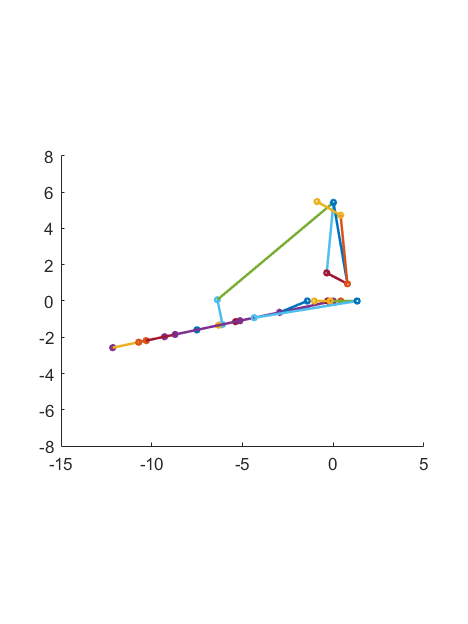

exportgraphics(f, 'figures/inverse-verification-case2-init-pose-top.png', 'Resolution', 600);

### Case 2: Final Pose

#### Front View

f = figure();
set(f,'Units',"centimeters","OuterPosition",[0, 0, 9.9, 13.2]);
thumb_simulation(case2_sim_theta1.', case2_sim_theta1_.', [0 -1 0]);

(-5.453337e+01, -2.999997e+01)


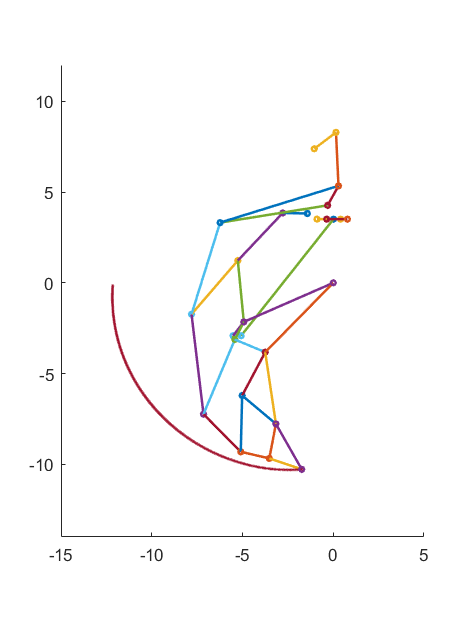

exportgraphics(f, 'figures/inverse-verification-case2-final-pose-front.png', 'Resolution', 600);

#### Top View

f = figure();
set(f,'Units',"centimeters","OuterPosition",[0, 0, 9.9, 13.2]);
thumb_simulation(case2_sim_theta1.', case2_sim_theta1_.', [0 0 1]);

(-5.453337e+01, -2.999997e+01)


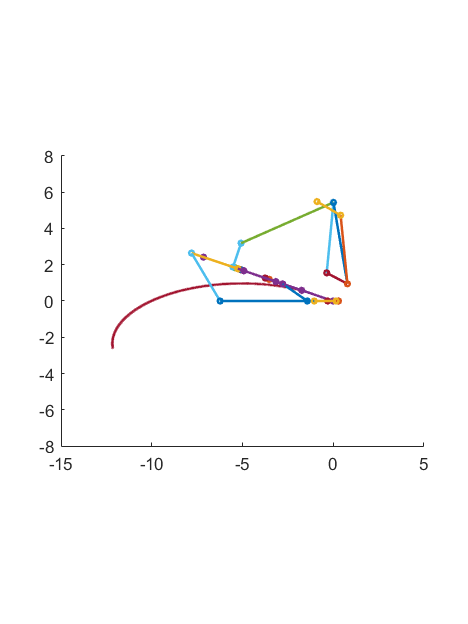

exportgraphics(f, 'figures/inverse-verification-case2-final-pose-top.png', 'Resolution', 600);


%view([0 0 1]); % top-view
%view([0 -1 0]); % front-view
%view([-8 -5 5]); % isometric view
%view([0 -0.5 0.5]);
%view([1 0 0]); % right-view
%view([0 1 0]); % back-view
case1_sim_theta1(1)

ans = 8.4742

case2_sim_theta1_(1)

ans = 11.9487